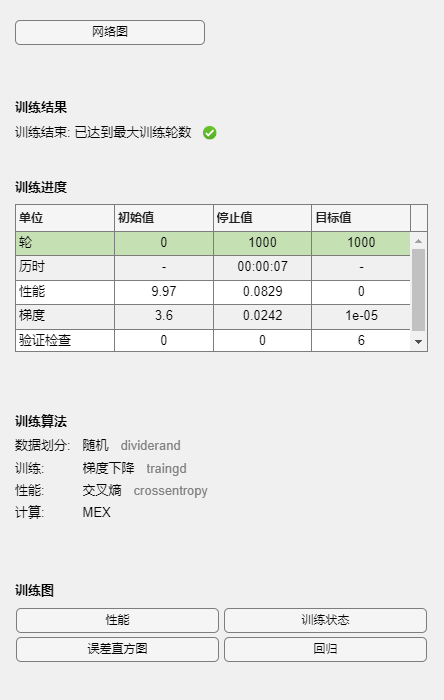

load 5FoldCV-3-6-9.mat

score=zeros(1,4500);
predictLabel=zeros(1,4500);
accuracy=zeros(1,5);

%configure Net
net=feedforwardnet(10,'traingd');
net.divideParam.trainRatio = 1; % training set [%]
net.divideParam.valRatio = 0; % validation set [%]
net.divideParam.testRatio = 0; % test set [%]
net.inputs{1}.processFcns = {}; % modify the process function for inputs
net.outputs{2}.processFcns = {}; % modify the process function for outputs
net.layers{1}.transferFcn = 'poslin'; % the transfer function for the first layer: ReLU
net.layers{2}.transferFcn = 'softmax'; % the transfer function for the second layer
net.performFcn = 'crossentropy'; % loss function
%%Adjust Training Parameters
net.trainParam.epochs = 1000;
net.trainParam.lr = 0.1; % learning rate.

for i=1:5
    trainIdx=cvp_369.training(i);
    testIdx=cvp_369.test(i);
    training_label=class_369(1,trainIdx);
    training_instance=digitNormalize(:,trainIdx);
    test_label=class_369(1,testIdx);
    test_instance=digitNormalize(:,testIdx);

    %training
    model=train(net,training_instance,training_label);

    %test
    score(1,testIdx)=sim(model,test_instance);

    %Obtain Label
    predictLabel(1,score<0.5)=0;
    predictLabel(1,score>=0.5)=1;
    
    %compute accuracy
    accuracy(1,i)=(sum(predictLabel(1,testIdx)==class_369(1,testIdx)))/size(test_label,2);
end

accuracy_average=mean(accuracy,2);
disp(accuracy);

    0.9722    0.9644    0.9656    0.9589    0.9411



disp(accuracy_average);

    0.9604



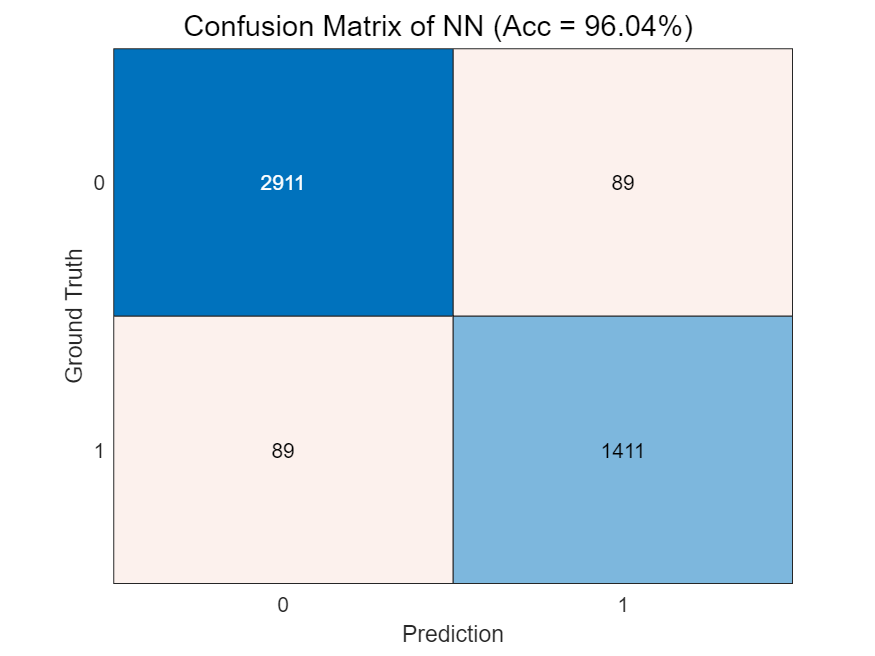


%plot figure
figure(1)
confusionchart(class_369.',predictLabel.');
Title = sprintf('Confusion Matrix of NN (Acc = %.2f%%)',accuracy_average*100);
sgtitle(Title);
xlabel('Prediction');ylabel('Ground Truth')


figure(2)
[FPR_NN,TPR_NN,T,AUC]=perfcurve(class_369.',predictLabel.',1);
disp(AUC);

    0.9555



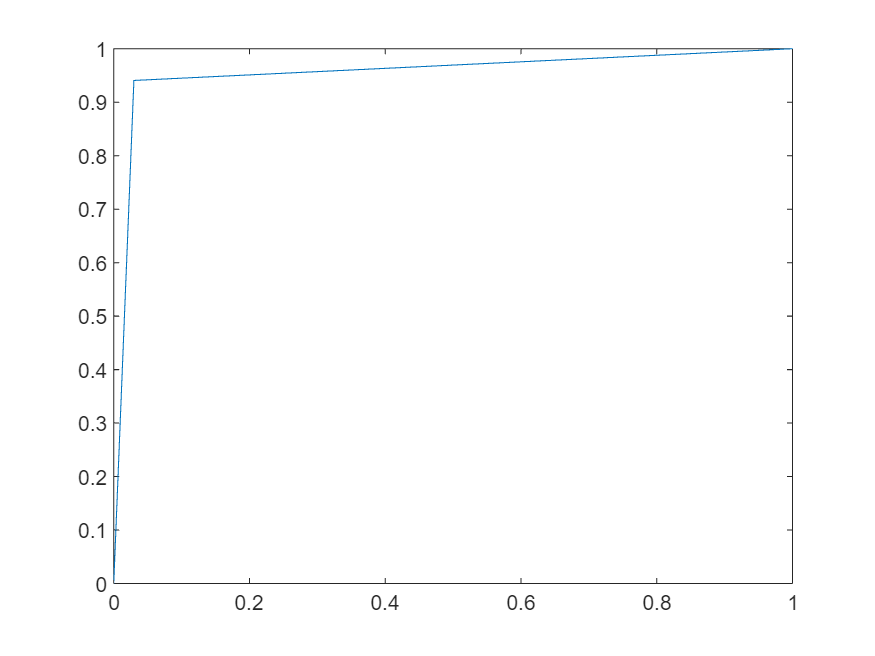

plot(FPR_NN,TPR_NN)

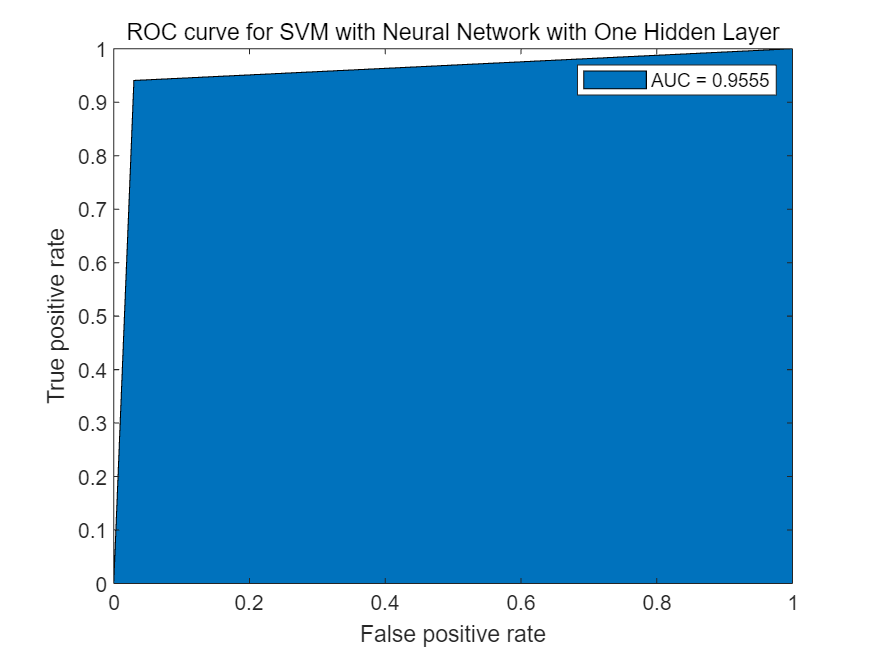

area(FPR_NN,TPR_NN);
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC curve for SVM with Neural Network with One Hidden Layer')
legend(['AUC = ', num2str(AUC)]);
box on

save nn_result